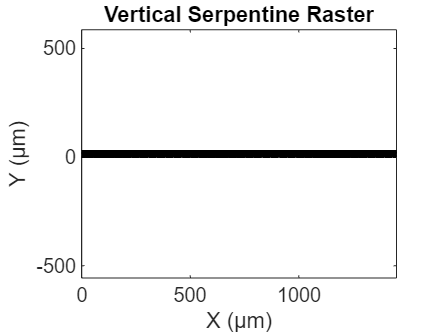

% ============================================================
% USER CONFIGURATION
% ============================================================

stepSize_x_um = 0.8;   % µm
stepSize_y_um = 0.8;   % µm

length_x_um   = 650+800;  % µm
length_y_um   = 30;    % µm

start_x_um    = 0;     % µm
start_y_um    = 0;     % µm

tempFP = "_temp_2D_coords.txt"; % temporary filepath for importing to WP

% ============================================================
% NO CONFIG BELOW THIS POINT
% ============================================================

% End points
end_x_um = start_x_um + length_x_um;
end_y_um = start_y_um + length_y_um;

% Axis vectors
x_um = start_x_um : stepSize_x_um : end_x_um;
y_um = start_y_um : stepSize_y_um : end_y_um;

% Create grid (Ny × Nx)
[X, Y] = meshgrid(x_um, y_um);

% ------------------------------------------------------------
% SERPENTINE ORDER (VERTICAL SCAN LINES)
% ------------------------------------------------------------

% Flip every other column to create a snake
flipCols = 2:2:size(X,2);
X(:,flipCols) = flipud(X(:,flipCols));
Y(:,flipCols) = flipud(Y(:,flipCols));

% Linearize into path order
coordsXY = [X(:), Y(:)];

% ------------------------------------------------------------
% VISUAL CHECK
% ------------------------------------------------------------
figure;
plot(coordsXY(:,1), coordsXY(:,2), '-k');
axis equal;
xlabel('X (µm)');
ylabel('Y (µm)');
title('Vertical Serpentine Raster');


% STORE COORDINATES
writematrix(coordsXY, tempFP)
importFile(hWP, tempFP)

delete(tempFP)